# Análisis de activación de reglas de VRUs

## Regla MovinPed escenario baja densidad 

evaluar escenario y proporción de activación  de forma genarl:   Total de veces que en realidad se activó / Total activacion (si todos entran a la regla) - Dsagregado por VRU


fid=fopen('TxNodes-MovinPed-S11-V0-DEN-0.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);

%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2}) ; str2num(tlines{j+3})]';


ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        if LD_Nodes(i,4)>= 1 %((delta_t*10)-1)
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
    end  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     27    28    28    28    28    28    28    29    30    30    30    30    30    30    30    31    31    32    32    32
    35    36    36    36    36    36    38    38    38    37    37    38    38    38    39    39    40    40    41    41
   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102   102
    44    44    43    43    44    43    43    43    43    43    41    42    42    42    43    42    42    43    43    43


sum(ind2)

ans =    208   210   209   209   210   209   211   212   213   212   210   212   212   212   214   214   215   217   218   218



mean(sum(ind2))

ans = 212.2500

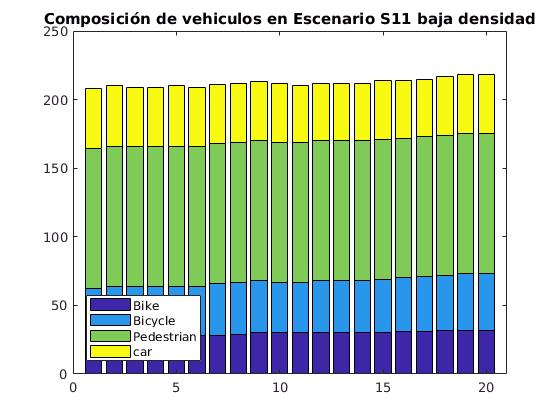



figure (1)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S11 baja densidad');
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])


ind3

ind3 =     27    28    28    28    28    28    28    29    30    30    30    30    30    30    30    31    31    32    32    32
    35    36    36    36    36    36    38    38    38    37    37    38    38    38    39    39    40    40    41    41
    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sum(ind3)

ans =     91    93    93    93    93    93    95    96    97    96    96    97    97    97    98    99   100   101   102   102



mean(sum(ind3))

ans = 96.4500

## Proporción de nodos transmisores (en los 20 seg de simulación) / nodos en el escenario 

ind3./ind2

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843    0.2843
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mean((ind3./ind2),2)

ans =     1.0000
    1.0000
    0.2843
         0


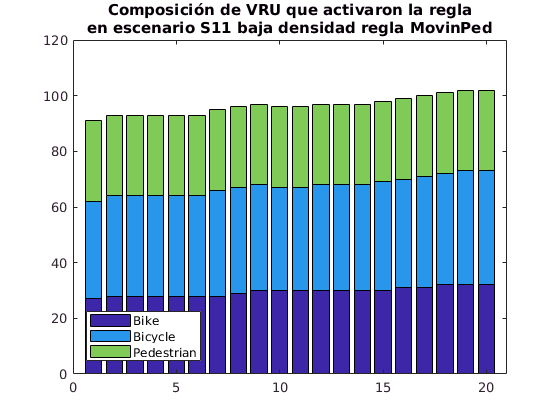


figure (2)
bar(ind3','stacked')
title({'Composición de VRU que activaron la regla','en escenario S11 baja densidad regla MovinPed'})
legend('Bike','Bicycle','Pedestrian','Location','SouthWest');
xlim([0 21])

## Regla MovinPed escenario alta densidad 



fid=fopen('TxNodes-MovinPed-S11-V0-DEN-1.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);

%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2}) ; str2num(tlines{j+3})]';


ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        if LD_Nodes(i,4)>=((delta_t*10)-1)
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
    end  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     36    36    37    38    38    38    39    38    39    39    40    40    41    41    42    42    43    44    44    44
    68    68    68    68    68    68    67    67    67    67    67    67    67    67    68    67    66    67    67    67
   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212
    78    78    77    76    76    76    76    75    75    75    74    74    73    73    72    72    71    70    71    71


sum(ind2)

ans =    394   394   394   394   394   394   394   392   393   393   393   393   393   393   394   393   392   393   394   394



mean(sum(ind2))

ans = 393.4000

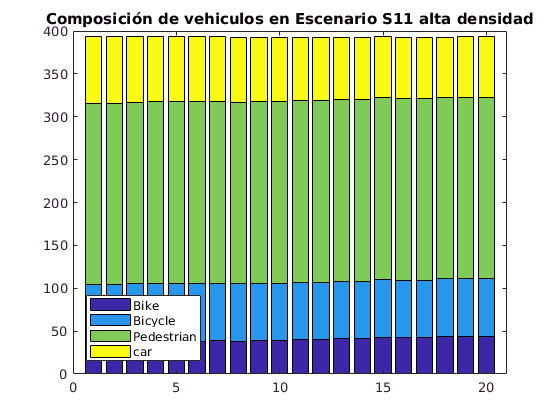



figure (3)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S11 alta densidad');
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])


ind3

ind3 =     36    36    37    38    38    38    39    38    39    39    40    40    41    41    42    42    43    44    44    44
    68    68    68    68    68    68    67    67    67    67    67    67    67    67    68    67    66    67    67    67
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sum(ind3)

ans =    104   104   105   106   106   106   106   105   106   106   107   107   108   108   110   109   109   111   111   111



mean(sum(ind3))

ans = 107.2500

## Proporción de nodos transmisores (en los 20 seg de simulación) / nodos en el escenario 

ind3./ind2

ans =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


mean((ind3./ind2),2)

ans =      1
     1
     0
     0


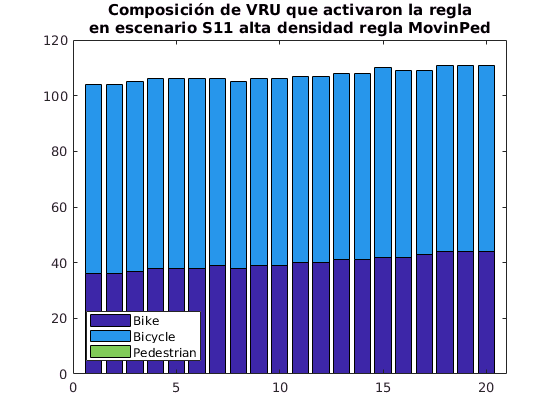


figure (4)
bar(ind3','stacked')
title({'Composición de VRU que activaron la regla','en escenario S11 alta densidad regla MovinPed'})
legend('Bike','Bicycle','Pedestrian','Location','SouthWest');
xlim([0 21])

## Regla OnStreet escenario baja densidad 


fid=fopen('TxNodes-OnStreet-S11-DEN-0.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);

%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2}) ; str2num(tlines{j+3})]';


ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        if LD_Nodes(i,4) >= floor((delta_t*10)*0)+9 % ((delta_t*10)-1)
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
    end  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     36    36    37    38    38    38    39    38    39    39    40    40    41    41    42    42    43    44    44    44
    68    68    68    68    68    68    67    67    67    67    67    67    67    67    68    67    66    67    67    67
   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212
    78    78    77    76    76    76    76    75    75    75    74    74    73    73    72    72    71    70    71    71


sum(ind2)

ans =    394   394   394   394   394   394   394   392   393   393   393   393   393   393   394   393   392   393   394   394



mean(sum(ind2))

ans = 393.4000

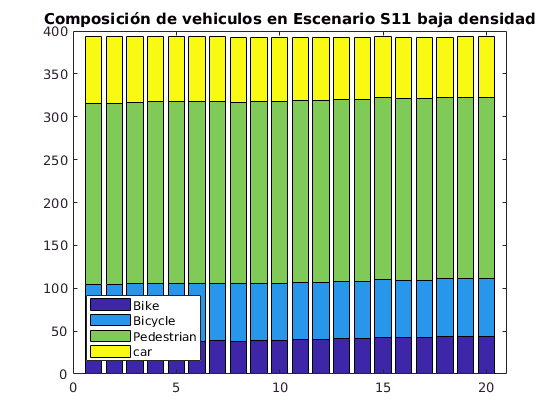



figure (5)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S11 baja densidad');
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])


ind3

ind3 =     36    36    37    38    38    38    39    38    39    39    40    40    41    41    42    42    43    44    44    44
    68    68    68    68    68    68    67    67    67    67    67    67    67    67    68    67    66    67    67    67
    17    17    17    17    17    17    17    17    17    17    17    17    17    17    17    17    17    17    17    17
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sum(ind3)

ans =    121   121   122   123   123   123   123   122   123   123   124   124   125   125   127   126   126   128   128   128



mean(sum(ind3))

ans = 124.2500

## Proporción de nodos transmisores (en los 20 seg de simulación) / nodos en el escenario 

ind3./ind2

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mean((ind3./ind2),2)

ans =     1.0000
    1.0000
    0.0802
         0


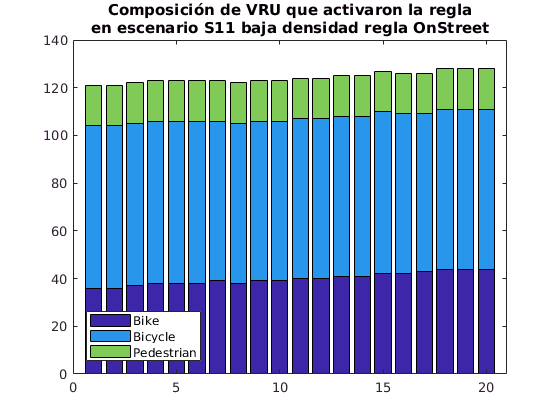


figure (6)
bar(ind3','stacked')
title({'Composición de VRU que activaron la regla','en escenario S11 baja densidad regla OnStreet'})
legend('Bike','Bicycle','Pedestrian','Location','SouthWest');
xlim([0 21])

## Regla OnStreet escenario alta densidad 



fid=fopen('TxNodes-OnStreet-S11-DEN-1.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);

%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2}) ; str2num(tlines{j+3})]';


ind2 = zeros(4,20);
ind3 = zeros(4,20);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    delta_t=fin_n-ini_n;
    if delta_t > 0
        ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
        if LD_Nodes(i,4) >= floor((delta_t*10)*0.1) % ((delta_t*10)-1)
            ind3(LD_Nodes(i,3),ini_n:fin_n)= ind3(LD_Nodes(i,3),ini_n:fin_n)+1;
        end
    end  
end 

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind2

ind2 =     36    36    37    38    38    38    39    38    39    39    40    40    41    41    42    42    43    44    44    44
    68    68    68    68    68    68    67    67    67    67    67    67    67    67    68    67    66    67    67    67
   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212
    78    78    77    76    76    76    76    75    75    75    74    74    73    73    72    72    71    70    71    71


sum(ind2)

ans =    394   394   394   394   394   394   394   392   393   393   393   393   393   393   394   393   392   393   394   394



mean(sum(ind2))

ans = 393.4000



figure (7)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario S11 alta densidad');
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 21])


ind3

ind3 =     36    36    37    38    38    38    39    38    39    39    40    40    41    41    42    42    43    44    44    44
    68    68    68    68    68    68    67    67    67    67    67    67    67    67    68    67    66    67    67    67
    17    17    17    17    17    17    17    17    17    17    17    17    17    17    17    17    17    17    17    17
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sum(ind3)

ans =    121   121   122   123   123   123   123   122   123   123   124   124   125   125   127   126   126   128   128   128



mean(sum(ind3))

ans = 124.2500

## Proporción de nodos transmisores (en los 20 seg de simulación) / nodos en el escenario 

ind3./ind2

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802    0.0802
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


mean((ind3./ind2),2)

ans =     1.0000
    1.0000
    0.0802
         0


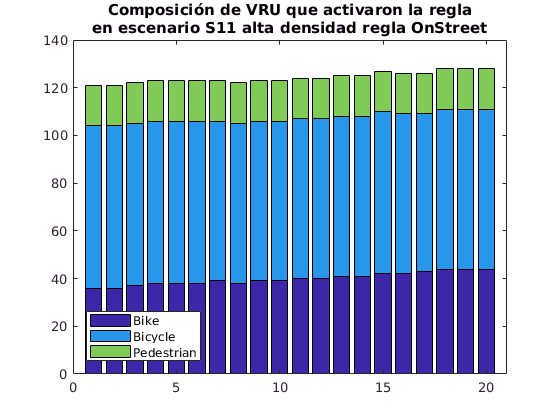


figure (8)
bar(ind3','stacked')
title({'Composición de VRU que activaron la regla','en escenario S11 alta densidad regla OnStreet'})
legend('Bike','Bicycle','Pedestrian','Location','SouthWest');
xlim([0 21])